# The Quantum Mouse - Part I

## Fock Space Representation of a Maze World

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)*, *[*Werner Meyer*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/m-sc-werner-meyer)*, *[*Ronald Römer*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/dr-ing-ronald-roemer)*, *[*Peter beim Graben*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/dr-rer-nat-peter-beim-graben)*, and *[*Markus Huber*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/dipl-math-markus-huber)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

fock.addFockBoxPaths();

## 1 A Simple Mouse-Maze World and its Representation in a Fock Space

**1.1 The Fock Maze**

Let's consider a mouse living in a simple 2$\times$2 maze as shown in Fig. 1, with cheese in the top-right corner.

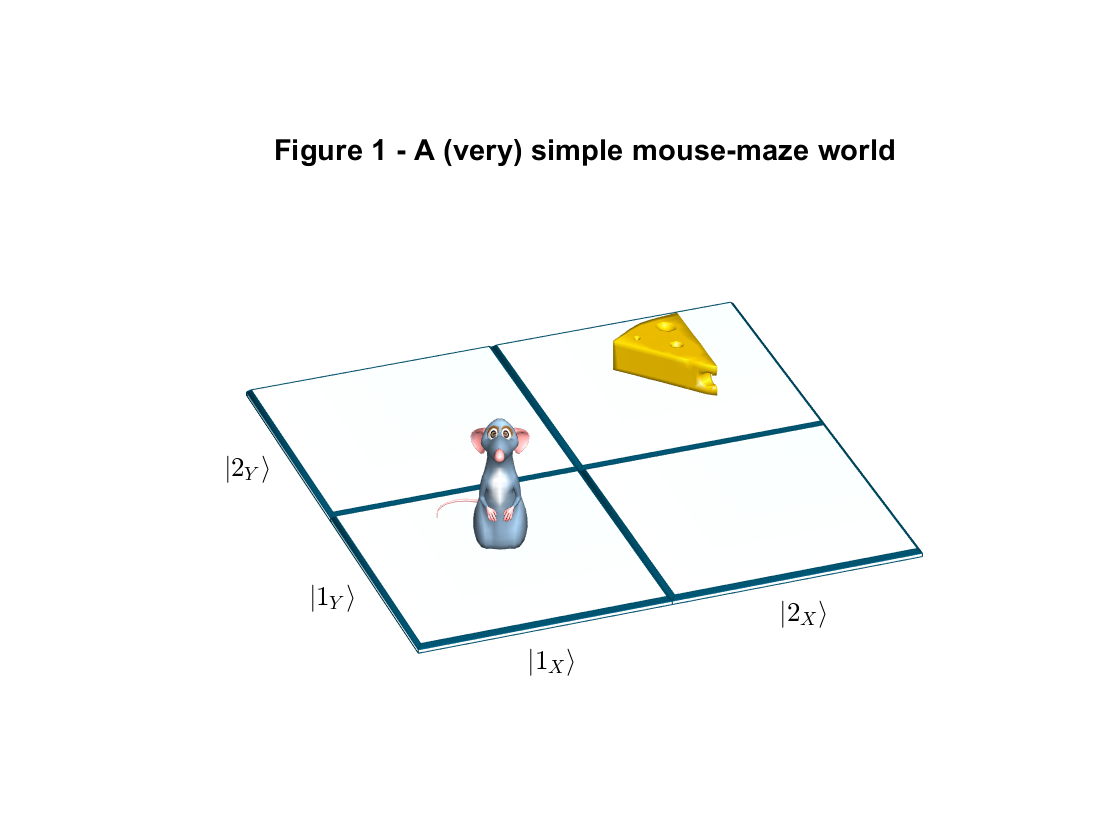

figure;
mmp = MouseMazePlot([2 2]);
mmp.addCheese(2,2);
mmp.addMouse(1,1,1,200);
title('Figure 1 - A (very) simple mouse-maze world');

First, we express the x-coordinate in a two-dimensional Fock space

        
$$H_X=span\big(|1_X\rangle,|2_X\rangle\big)$$


HX = fockbasis({'1X' '2X'}); disp(HX);

  fockbasis

    Dimensions: 3
    Sectors   : 2
    Type      : canonical

    ε                   	1
    1X                  	2
    2X                  	3


which contains one base $|n_X\rangle$ for each coordinate value.

X1 = fockobj.bket('1X'); disp(X1);

  fockobj

    Type: ket 

    (1X,ε)              	1.000000


X2 = fockobj.bket('2X'); disp(X2);

  fockobj

    Type: ket 

    (2X,ε)              	1.000000


The canonical realization of $H_X$ is shown in Fig. 2.

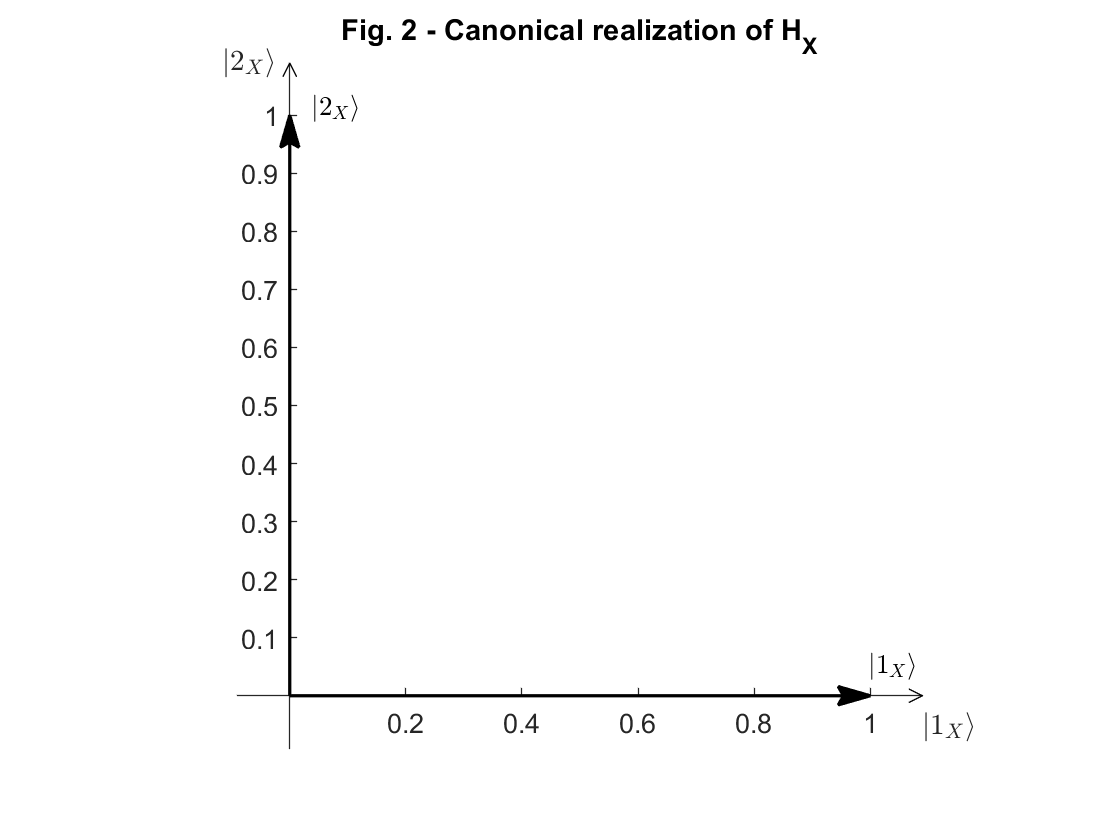

figure;
fock.plotVector({X1 X2}, 'axesLocation', 'origin', ...
  'axesNames', {'$|1_X\rangle$' '$|2_X\rangle$'}, ...
  'vecLabels', {'$|1_X\rangle$' '$|2_X\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0.05] [0.08 -0.08]});    
title('Fig. 2 - Canonical realization of H_X');

Then we do the same for the y-coordinate and the cheese value

        $H_Y=span\big(|1_Y\rangle,|2_Y\rangle\big)$    and     $H_C=span\big(|0_C\rangle,|1_C\rangle\big)$,

HY = fockbasis({'1Y' '2Y'});
HC = fockbasis({'0C' '1C'});

where $|0_C\rangle$ means "no cheese" and $|1_C\rangle$ means "cheese".

The maze world can be described in a tensor product space of $H_X$, $H_Y$, and $H_C$

        $H = H_X\otimes H_Y\otimes H_C$.

H = [HX HY HC]; disp(H);

  fockbasis

    Dimensions: 27
    Sectors   : 4
    Type      : canonical

    ε                   	1
    0C                  	2
    1C                  	3
    1X                  	4
    1X⊗0C               	5
    1X⊗1C               	6
    1X⊗1Y               	7
    1X⊗1Y⊗0C            	8
    1X⊗1Y⊗1C            	9
    1X⊗2Y               	10
    1X⊗2Y⊗0C            	11
    1X⊗2Y⊗1C            	12
    1Y                  	13
    1Y⊗0C               	14
    1Y⊗1C               	15
    2X                  	16
    2X⊗0C               	17
    2X⊗1C               	18
    2X⊗1Y               	19
    2X⊗1Y⊗0C            	20
    2X⊗1Y⊗1C            	21
    2X⊗2Y               	22
    2X⊗2Y⊗0C            	23
    2X⊗2Y⊗1C            	24
    2Y                  	25
    2Y⊗0C               	26
    2Y⊗1C               	27


**1.2 The Actual Situation in the Maze**

The actual situation---cheese at position (1,1) and no cheese everywhere else---can be expressed by a (unnormalized) state $|w\rangle$ in $H$

        
$$|w\rangle = |1_X1_Y0_C\rangle \oplus |1_X2_Y0_C\rangle 
              \oplus |2_X1_Y0_C\rangle \oplus |2_X2_Y1_C\rangle,$$


where $|n_Xm_Yl_C\rangle = |n_X\rangle \otimes |m_Y\rangle \otimes |l_C\rangle$ is a tensor product of bases from $H_X$, $H_Y$, and $H_C$.

X1 = fockobj.bket('1X');   % base |1_X>
X2 = fockobj.bket('2X');   % base |2_X>
Y1 = fockobj.bket('1Y');   % ...
Y2 = fockobj.bket('2Y');
C0 = fockobj.bket('0C');
C1 = fockobj.bket('1C');

w = [X1 Y1 C0] + [X1 Y2 C0] + [X2 Y1 C0] + [X2 Y2 C1];
w.name = 'maze state'; disp(w);

  fockobj

    Name: maze state 
    Type: ket 

    (1X⊗1Y⊗0C,ε)        	1.000000
    (1X⊗2Y⊗0C,ε)        	1.000000
    (2X⊗1Y⊗0C,ε)        	1.000000
    (2X⊗2Y⊗1C,ε)        	1.000000


*Note*: The [`fockobj`](matlab:helpPopup fockobj) class defines the horizontal concatenation operator as Kronecker tensor product, i.e., `[X Y]` is a shortcut for [`kron`](matlab:helpPopup fockobj/kron)`(X,Y)`.

## 2 Finding Functional Dependencies Between Values

**2.1 Is Cheese a Function of the X-Coordinate?**

To find this out, we create two projectors, one on the sub-space containing no cheese (aka. the "hunger space", $H_{0C}$) and one on the sub-space containg cheese (aka. the "cheese space", $H_{1C}$)

        
$$P_{0C} = \bigoplus\limits_{n=1}^2\bigoplus\limits_{m=1}^2\;
           |n_Xm_Y0_C\rangle\langle n_Xm_Y0_C|, \qquad
  P_{1C} = \bigoplus\limits_{n=1}^2 \bigoplus\limits_{m=1}^2\;
           |n_Xm_Y1_C\rangle\langle n_Xm_Y1_C|.$$


PC0 = [X1 Y1 C0]*[X1 Y1 C0]' + [X1 Y2 C0]*[X1 Y2 C0]' ...
    + [X2 Y1 C0]*[X2 Y1 C0]' + [X2 Y2 C0]*[X2 Y2 C0]';
PC1 = [X1 Y1 C1]*[X1 Y1 C1]' + [X1 Y2 C1]*[X1 Y2 C1]' ...
    + [X2 Y1 C1]*[X2 Y1 C1]' + [X2 Y2 C1]*[X2 Y2 C1]';
PC0.name = 'hunger space projector'; disp(PC0);

  fockobj

    Name: hunger space projector 
    Type: linear operator 

    (1X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,2X⊗2Y⊗0C) 	1.000000


PC1.name = 'cheese space projector'; disp(PC1);

  fockobj

    Name: cheese space projector 
    Type: linear operator 

    (1X⊗1Y⊗1C,1X⊗1Y⊗1C) 	1.000000
    (1X⊗2Y⊗1C,1X⊗2Y⊗1C) 	1.000000
    (2X⊗1Y⊗1C,2X⊗1Y⊗1C) 	1.000000
    (2X⊗2Y⊗1C,2X⊗2Y⊗1C) 	1.000000


Multiplying these with the world state $|w\rangle$ gives the projections  $|w_{0C}\rangle$ and $|w_{1C}\rangle$ of the world state on the "hunger" and "cheese" spaces, respectively

        
$$|w_{0C}\rangle = P_{0C}|w\rangle,\qquad
  |w_{1C}\rangle = P_{1C}|w\rangle.$$


wC0 = PC0*w; wC0.name='hunger space'; disp(wC0);

  fockobj

    Name: hunger space 
    Type: ket 

    (1X⊗1Y⊗0C,ε)        	1.000000
    (1X⊗2Y⊗0C,ε)        	1.000000
    (2X⊗1Y⊗0C,ε)        	1.000000


wC1 = PC1*w; wC1.name='cheese space'; disp(wC1);

  fockobj

    Name: cheese space 
    Type: ket 

    (2X⊗2Y⊗1C,ε)        	1.000000


To find out which x-positions do not contain cheese and which do, we define a linear operator $P_X$ mapping a state $|w_{\cdot}\rangle$ on the x coordinate space

        
$$P_X = \bigoplus\limits_{n=1}^2 |n_X\rangle \left\langle
          n_X 
          \left(\bigoplus\limits_{m=1}^2 m_Y\right)
          \left(\bigoplus\limits_{l=0}^1 l_C\right)
        \right|$$


and apply it to the projections of the world state to the hunger and cheese spaces

        
$$|w_{nX\,0C}\rangle = P_X|w_{0C}\rangle = P_XP_{0C}|w\rangle,\qquad
  |w_{nX\,1C}\rangle = P_X|w_{1C}\rangle = P_XP_{1C}|w\rangle.$$


PX = X1*([X1 (Y1+Y2) (C0+C1)])' + X2*([X2 (Y1+Y2) (C0+C1)])';
PX.name = 'x coordinate space map'; disp(PX);

  fockobj

    Name: x coordinate space map 
    Type: linear operator 

    (1X,1X⊗1Y⊗0C)       	1.000000
    (1X,1X⊗1Y⊗1C)       	1.000000
    (1X,1X⊗2Y⊗0C)       	1.000000
    (1X,1X⊗2Y⊗1C)       	1.000000
    (2X,2X⊗1Y⊗0C)       	1.000000
    (2X,2X⊗1Y⊗1C)       	1.000000
    (2X,2X⊗2Y⊗0C)       	1.000000
    (2X,2X⊗2Y⊗1C)       	1.000000



wXC0 = PX*PC0*w; wXC0.name = 'hunger space on x axis'; disp(wXC0);

  fockobj

    Name: hunger space on x axis 
    Type: ket 

    (1X,ε)              	2.000000
    (2X,ε)              	1.000000


wXC1 = PX*PC1*w; wXC1.name = 'cheese space on x axis'; disp(wXC1);

  fockobj

    Name: cheese space on x axis 
    Type: ket 

    (2X,ε)              	1.000000


There is a functional dependency $C=f(X)$ of cheese from the x-coordinate, iff $|w_{nX\,0C}\rangle$ and $|w_{nX\,1C}\rangle$ are orthogonal, i.e. iff  $\langle w_{nX\,0C}|w_{nX\,1C}\rangle=0$. As this is not the case in our example,

        
$$C\neq f(X),$$


i.e. cheese is not a function of the x-coordinate. Fig. 3 shows  $|w_{nX\,0C}\rangle$ and $|w_{nX\,1C}\rangle$ in the $H_X$ coordinate space.

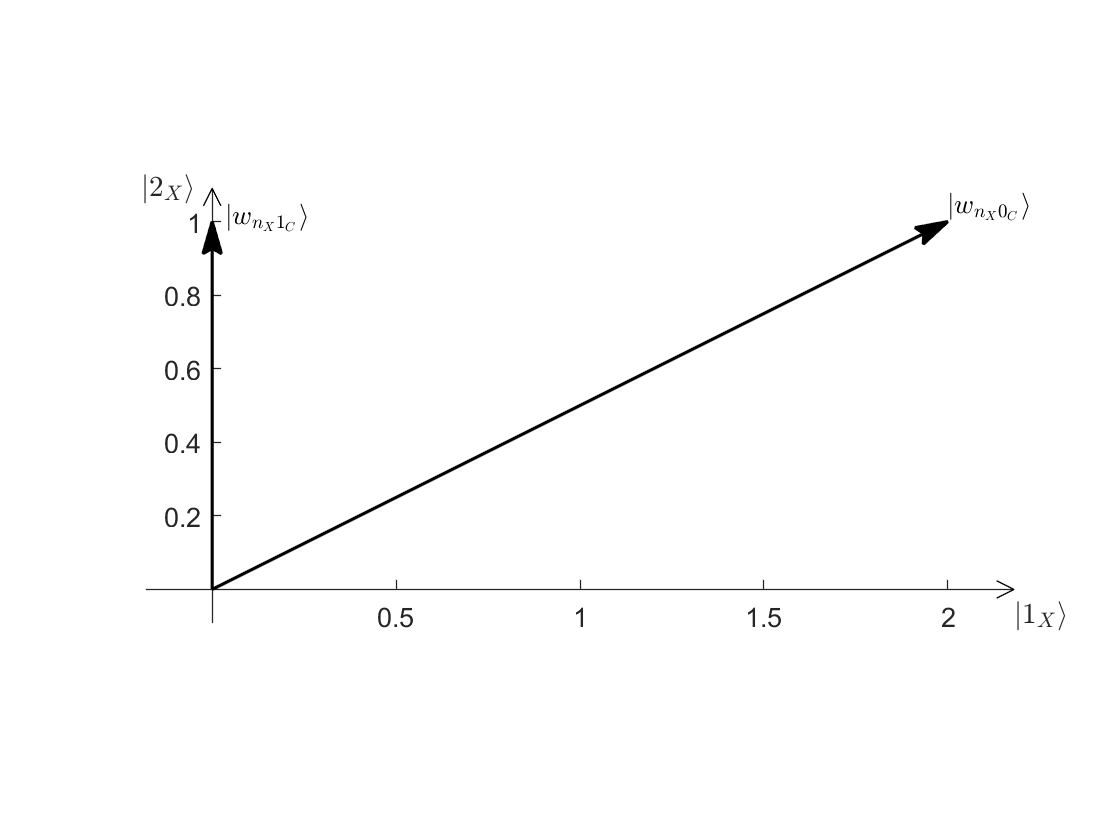

figure;
fock.plotVector({wXC0 wXC1},'axesLocation','origin', ...
  'axesNames', {'$|1_X\rangle$' '$|2_X\rangle$'}, ...
  'vecLabels',{'$|w_{n_X0_C}\rangle$' '$|w_{n_X1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0] [0.15 -0.08]});

if wXC0'*wXC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(X) \n']);

  C≠f(X) 


**2.2 Is Cheese a Function of the Y-Coordinate?**

Now we map the projection of the world state on the hunger and cheese space on the y coordinate space and test again whether the resulting vectors are orthogonal

        
$$|w_{mY\,0C}\rangle = P_YP_{0C}|w\rangle,\qquad
  |w_{mY\,1C}\rangle = P_YP_{1C}|w\rangle.$$


with

        
$$P_Y = \bigoplus\limits_{m=1}^2 |m_Y\rangle \left\langle
          \left(\bigoplus\limits_{n=1}^2 n_X\right)
          m_Y 
          \left(\bigoplus\limits_{l=0}^1 l_C\right)
        \right|.$$


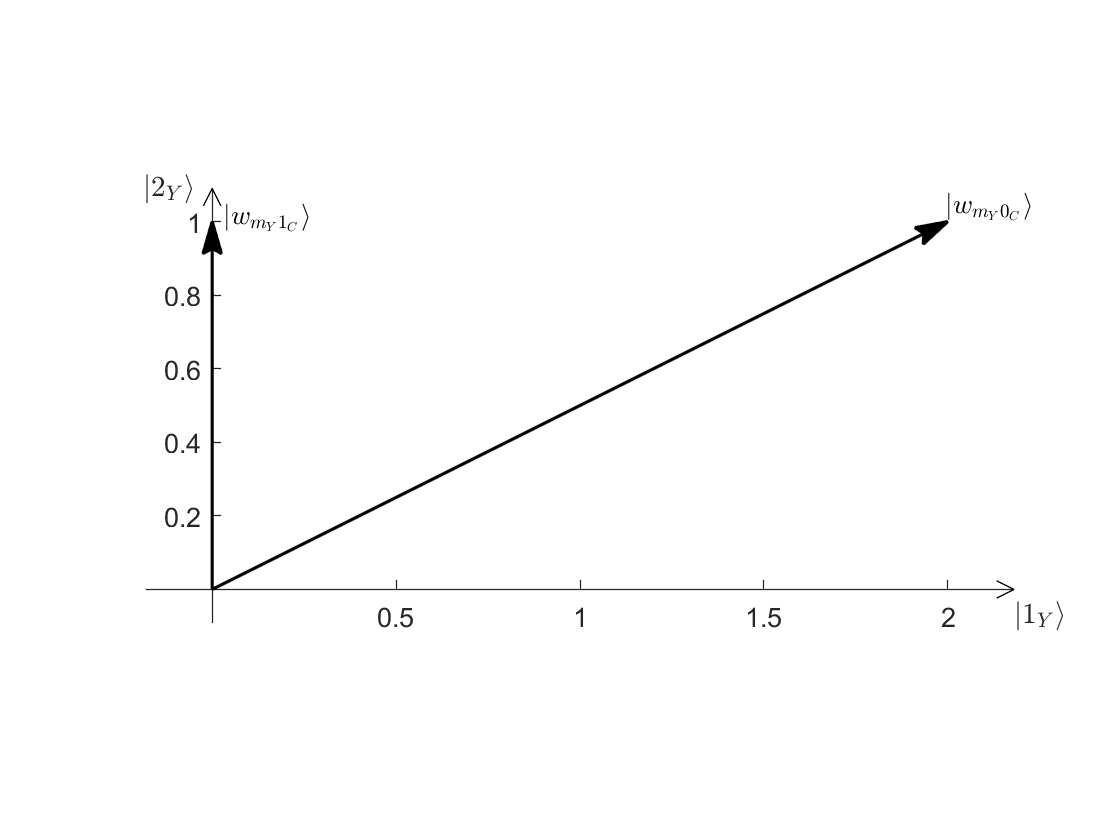

PY = Y1*([(X1+X2) Y1 (C0+C1)])' + Y2*([(X1+X2) Y2 (C0+C1)])';
PY.name = 'y coordinate space map';

wYC0 = PY*PC0*w; wYC0.name = 'hunger space on y axis';
wYC1 = PY*PC1*w; wYC1.name = 'cheese space on y axis';

figure;
fock.plotVector({wYC0 wYC1},'axesLocation','origin', ...
  'axesNames', {'$|1_Y\rangle$' '$|2_Y\rangle$'}, ...
  'vecLabels',{'$|w_{m_Y0_C}\rangle$' '$|w_{m_Y1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0] [0.15 -0.08]});

if wYC0'*wYC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(Y) \n']);

  C≠f(Y) 


The result is the same

        
$$\langle w_{mY\,0C}|w_{mY\,1C}\rangle\neq 0 \Leftrightarrow
  C\neq f(X).$$


Fig. 4 shows a plot of $|w_{mY\,0C}\rangle$ and $|w_{mY\,1C}\rangle$.

**2.3 Finally, Is Cheese a Function of (X,Y) Coordinate Tuples?**

Last, we try a mapping on the entire x-y coordinate plane

        
$$|w_{nX\,mY\,0C}\rangle = P_{XY}P_{0C}|w\rangle,\qquad
  |w_{nX\,mY\,1C}\rangle = P_{XY}P_{1C}|w\rangle.$$


with

        
$$P_{XY} = \bigoplus\limits_{n=1}^2\bigoplus\limits_{m=1}^2
             |n_Xm_Y\rangle \left\langle
               n_Xm_Y\left(\bigoplus_{l=0}^ll_C\right)
             \right|.$$


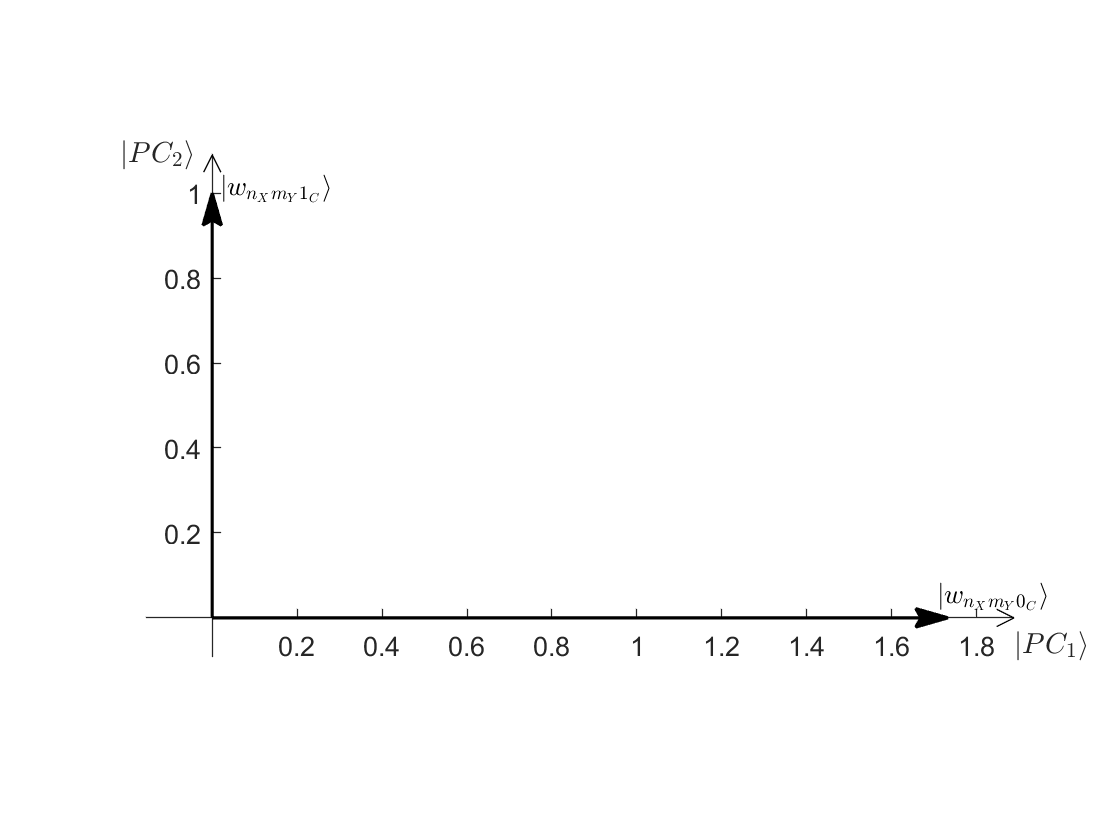

PXY = [X1 Y1]*[X1 Y1 (C0+C1)]' + [X1 Y2]*[X1 Y2 (C0+C1)]' ...
    + [X2 Y1]*[X2 Y1 (C0+C1)]' + [X2 Y2]*[X2 Y2 (C0+C1)]';
PXY.name = 'x-y coordinate space map';

wXYC0 = PXY*PC0*w; wXYC0.name = 'hunger space on x-y plane';
wXYC1 = PXY*PC1*w; wXYC1.name = 'cheese space on x-y plane';

figure;
fock.plotVector({wXYC0 wXYC1},'axesLocation','origin', ...
  'vecLabels',{'$|w_{n_Xm_Y0_C}\rangle$' '$|w_{n_Xm_Y1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0.05] [0.15 -0.08]});

if wXYC0'*wXYC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(X,Y) \n']);

  C=f(X,Y) 


## 3 Excursus: Using Complex Fock Spaces

Binary values, such as the cheese flag in our example, can also be expressed by one base $|C\rangle$ with complex scalar factors, e.g.,

        
$$C\!=0\mapsto i\,|C\rangle,\qquad
C\!=1\mapsto |C\rangle.$$


clear C0 C1;
C = fockobj.bket('C');

All computations from above can be done with this fromulation as well:

% Maze state
w = [X1 Y1 1i*C] + [X1 Y2 1i*C] + [X2 Y1 1i*C] + [X2 Y2 C];
w.name = 'maze state'; disp(w);

  fockobj

    Name: maze state 
    Type: ket 

    (1X⊗1Y⊗C,ε)         	0.000000 + 1.000000i
    (1X⊗2Y⊗C,ε)         	0.000000 + 1.000000i
    (2X⊗1Y⊗C,ε)         	0.000000 + 1.000000i
    (2X⊗2Y⊗C,ε)         	1.000000



% Projectors
PC = [X1 Y1 C]*[X1 Y1 C]' + [X1 Y2 C]*[X1 Y2 C]' ...
   + [X2 Y1 C]*[X2 Y1 C]' + [X2 Y2 C]*[X2 Y2 C]';
PC.name = 'hunger and cheese space projector'; disp(PC);

  fockobj

    Name: hunger and cheese space projector 
    Type: linear operator 

    (1X⊗1Y⊗C,1X⊗1Y⊗C)   	1.000000
    (1X⊗2Y⊗C,1X⊗2Y⊗C)   	1.000000
    (2X⊗1Y⊗C,2X⊗1Y⊗C)   	1.000000
    (2X⊗2Y⊗C,2X⊗2Y⊗C)   	1.000000



PX = X1*([X1 (Y1+Y2) C])' + X2*([X2 (Y1+Y2) C])';
PX.name = 'x coordinate space map'; disp(PX);

  fockobj

    Name: x coordinate space map 
    Type: linear operator 

    (1X,1X⊗1Y⊗C)        	1.000000
    (1X,1X⊗2Y⊗C)        	1.000000
    (2X,2X⊗1Y⊗C)        	1.000000
    (2X,2X⊗2Y⊗C)        	1.000000



PY = Y1*([(X1+X2) Y1 C])' + Y2*([(X1+X2) Y2 C])';
PY.name = 'y coordinate space map';

PXY = [X1 Y1]*[X1 Y1 C]' + [X1 Y2]*[X1 Y2 C]' ...
    + [X2 Y1]*[X2 Y1 C]' + [X2 Y2]*[X2 Y2 C]';
PXY.name = 'x-y coordinate space map';

% Test functional dependency X->C
wXC = PX*PC*w; wXC.name = 'hunger and cheese space on x axis'; disp(wXC);

  fockobj

    Name: hunger and cheese space on x axis 
    Type: ket 

    (1X,ε)              	0.000000 + 2.000000i
    (2X,ε)              	1.000000 + 1.000000i


wXC0 = imag(wXC); wXC0.name = 'hunger space on x axis'; disp(wXC0);

  fockobj

    Name: hunger space on x axis 
    Type: ket 

    (1X,ε)              	2.000000
    (2X,ε)              	1.000000


wXC1 = real(wXC); wXC1.name = 'cheese space on x axis'; disp(wXC1);

  fockobj

    Name: cheese space on x axis 
    Type: ket 

    (2X,ε)              	1.000000



figure;
fock.plotVector({wXC0 wXC1},'axesLocation','origin', ...
  'axesNames', {'$|1_X\rangle$' '$|2_X\rangle$'}, ...
  'vecLabels',{'$|w_{n_X0_C}\rangle$' '$|w_{n_X1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0] [0.15 -0.08]});

if wXC0'*wXC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(X) \n']);

  C≠f(X) 



% Test functional dependency Y->C
wYC = PY*PC*w; wYC.name = 'hunger and cheese space on y axis'; disp(wYC);

  fockobj

    Name: hunger and cheese space on y axis 
    Type: ket 

    (1Y,ε)              	0.000000 + 2.000000i
    (2Y,ε)              	1.000000 + 1.000000i


wYC0 = imag(wYC); wYC0.name = 'hunger space on y axis'; disp(wYC0);

  fockobj

    Name: hunger space on y axis 
    Type: ket 

    (1Y,ε)              	2.000000
    (2Y,ε)              	1.000000


wYC1 = real(wYC); wYC1.name = 'cheese space on y axis'; disp(wYC1);

  fockobj

    Name: cheese space on y axis 
    Type: ket 

    (2Y,ε)              	1.000000



figure;
fock.plotVector({wYC0 wYC1},'axesLocation','origin', ...
  'axesNames', {'$|1_Y\rangle$' '$|2_Y\rangle$'}, ...
  'vecLabels',{'$|w_{m_Y0_C}\rangle$' '$|w_{m_Y1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0] [0.15 -0.08]});

if wYC0'*wYC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(Y) \n']);

  C≠f(Y) 



% Test functional dependency (X,Y)->C
wXYC = PXY*PC*w; wXYC.name = 'hunger and cheese space on y axis'; disp(wXYC);

  fockobj

    Name: hunger and cheese space on y axis 
    Type: ket 

    (1X⊗1Y,ε)           	0.000000 + 1.000000i
    (1X⊗2Y,ε)           	0.000000 + 1.000000i
    (2X⊗1Y,ε)           	0.000000 + 1.000000i
    (2X⊗2Y,ε)           	1.000000


wXYC0 = imag(wXYC); wXYC0.name = 'hunger space on x-y plane'; disp(wXYC0);

  fockobj

    Name: hunger space on x-y plane 
    Type: ket 

    (1X⊗1Y,ε)           	1.000000
    (1X⊗2Y,ε)           	1.000000
    (2X⊗1Y,ε)           	1.000000


wXYC1 = real(wXYC); wXYC1.name = 'cheese space on x-y plane'; disp(wXYC1);

  fockobj

    Name: cheese space on x-y plane 
    Type: ket 

    (2X⊗2Y,ε)           	1.000000



figure;
fock.plotVector({wXYC0 wXYC1},'axesLocation','origin', ...
  'vecLabels',{'$|w_{n_Xm_Y0_C}\rangle$' '$|w_{n_Xm_Y1_C}\rangle$'}, ...
  'vecLabelOffs', {[-0.05 0.05] [0.15 -0.08]});

if wXYC0'*wXYC1==0; s='='; else; s=char(8800); end
fprintf(['  C' s 'f(X,Y) \n']);

  C=f(X,Y) 


## References

[1] M. Huber, R. Römer: *Agenten in höheren Spären - Quantenmechanische Situationsmodellierung kognitiver Systeme am Beispiel des Mouse-Maze-Problems*. In A. Berton et al.: Elektronische Sprachsignalverarbeitung 2018, Tagungsband der 29. Konferenz, TUDpress, S. 127-134, 2018. ISBN: 978-3-95908-128-3.